# `3 简单数据分析`

## `3.1 简单统计`

### `Q3.1 对下列矩阵分别求每列、每行的最大值、最小值、平均值、中位数、标准差。 并按第1、2、3列同时排序。 `


$$\begin{array}{ccccccc}
76 & 79 & 91 & 0 & 19 & 41 & 1\\
76 & 61 & 93 & 81 & 27 & 46 & 83\\
95 & 7 & 73 & 5 & 19 & 44 & 20\\
95 & 7 & 40 & 35 & 60 & 93 & 67\\
95 & 45 & 92 & 41 & 13 & 1 & 84
\end{array}$$


`求上述矩阵所有元素中的最大值、最小值，并求最大值、最小值所对应的行号、列号。 `

`求上述矩阵每行的和、每列的和、所有元素的和。`

A = [76 79 91 0 19 41 1;
    76 61 93 81 27 46 83;
    95 7 73 5 19 44 20;
    95 7 73 89 20 74 52;
    95 7 40 35 60 93 67;
    95 45 92 41 13 1 84];

#### `每列的最大值、最小值、平均值、中位数、标准差`

max(A,[],1)

ans =     95    79    93    89    60    93    84


min(A,[],1)

ans =     76     7    40     0    13     1     1


mean(A,1)

ans =    88.6667   34.3333   77.0000   41.8333   26.3333   49.8333   51.1667


median(A,1)

ans =    95.0000   26.0000   82.0000   38.0000   19.5000   45.0000   59.5000


std(A,0,1)

ans =     9.8116   31.8161   20.3863   37.1829   17.0841   31.4923   34.1492


#### `每行的最大值、最小值、平均值、中位数、标准差`

max(A,[],2)

ans =     91
    93
    95
    95
    95
    95


min(A,[],2)

ans =      0
    27
     5
     7
     7
     1


mean(A,2)

ans =    43.8571
   66.7143
   37.5714
   58.5714
   56.7143
   53.0000


median(A,2)

ans =     41
    76
    20
    73
    60
    45


std(A,0,2)

ans =    38.4640
   23.4002
   34.7460
   33.8864
   31.9412
   38.2056


#### `矩阵所有元素中的最大值、最小值`

max_val = max(A, [], 'all')

max_val = 95

min_val = min(A, [], 'all')

min_val = 0

#### `最大值、最小值所对应的行号、列号`

[row,col] = find(A == max_val)

row =      3
     4
     5
     6


col =      1
     1
     1
     1


[row,col] = find(A == min_val)

row = 1

col = 4

#### `每行的和`

sum(A,2)

ans =    307
   467
   263
   410
   397
   371


#### `每列的和`

sum(A,1)

ans =    532   206   462   251   158   299   307


#### `所有元素的和`

sum(A,'all')

ans = 2215

## `3.2 条形分布图`

#### `Q3.2 编程画出直线、`$\cos$`曲线、`$e^x$`曲线、`$x^2$`曲线（或其它多项式）等的条形分布图，总结这些曲线的统计规律`

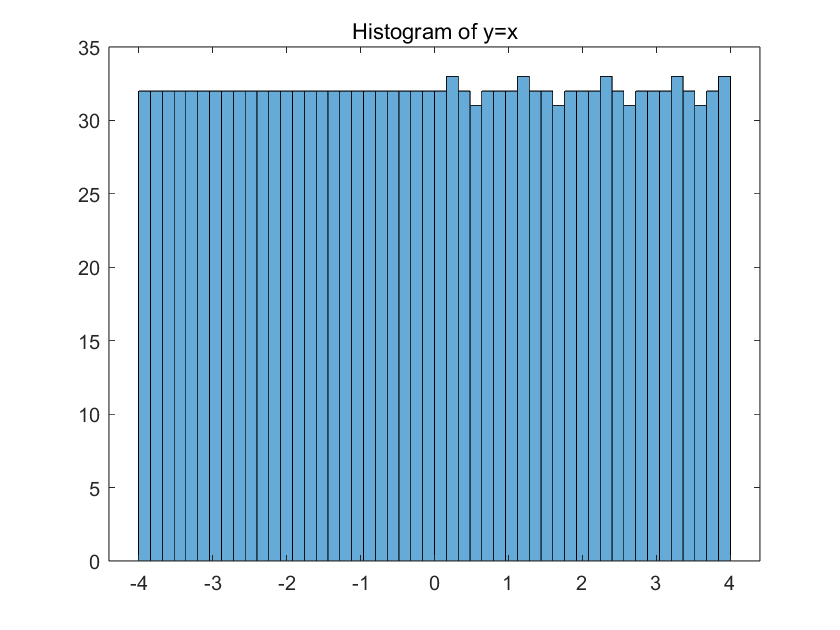

x = -4:0.005:4;
histogram(x,50)
title('Histogram of y=x')

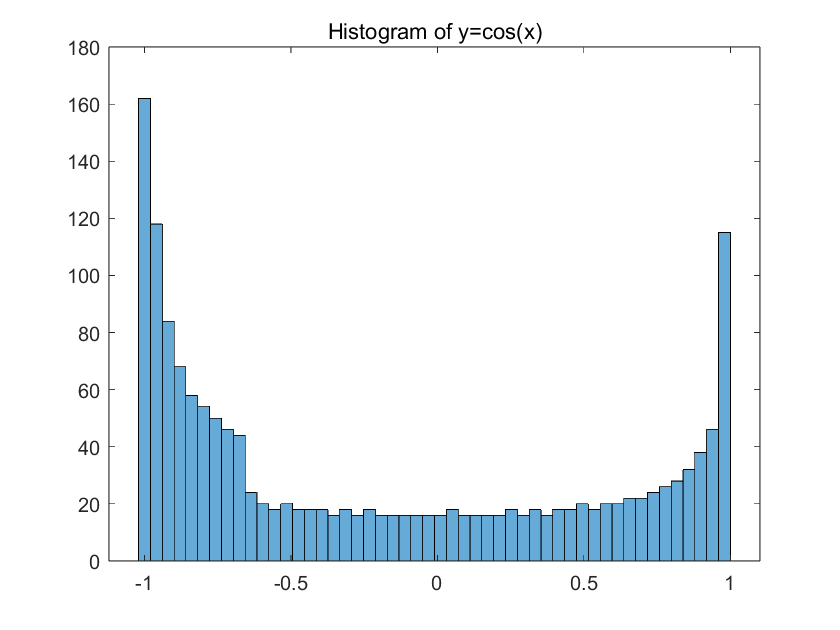

y = cos(x);
histogram(y,50)
title('Histogram of y=cos(x)')

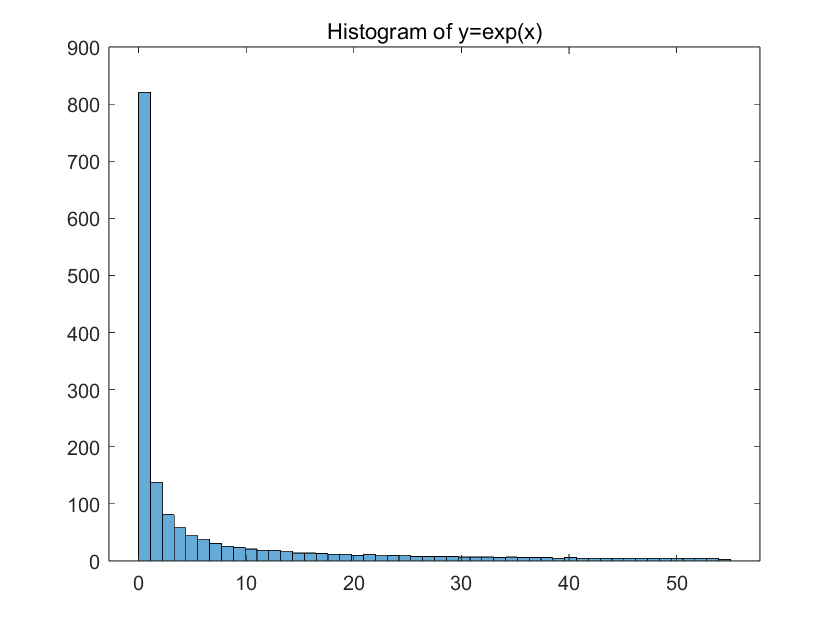

y = exp(x);
histogram(y,50)
title('Histogram of y=exp(x)')

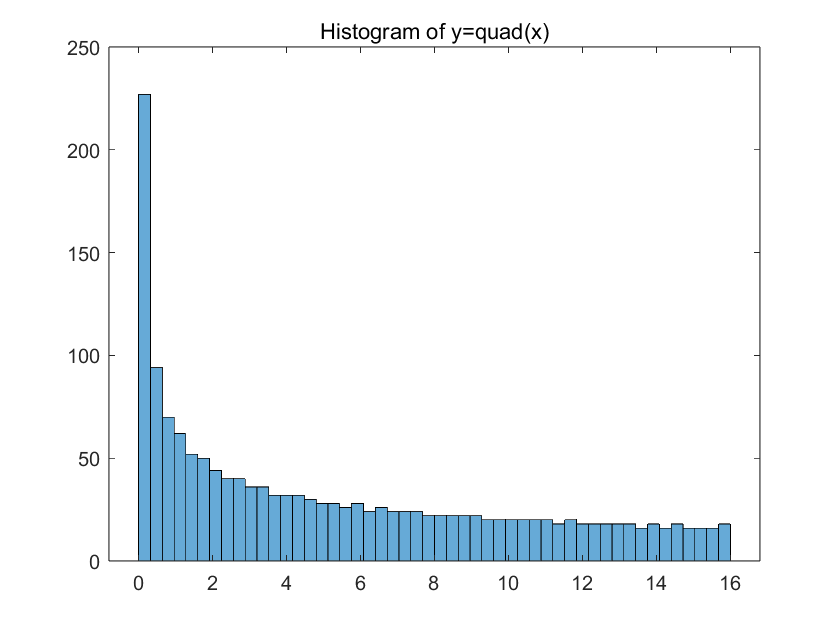

y = power(x,2);
histogram(y,50)
title('Histogram of y=quad(x)')

## `3.3 随机数`

#### `Q3.3 产生一个1行1000列的正态分布随机数矩阵，要求正态分布的均值为2、方差为0.1。用hist 查看其条形分布图，与均值为0、方差为1的正态分布随机数的条形分布图有何不同？`

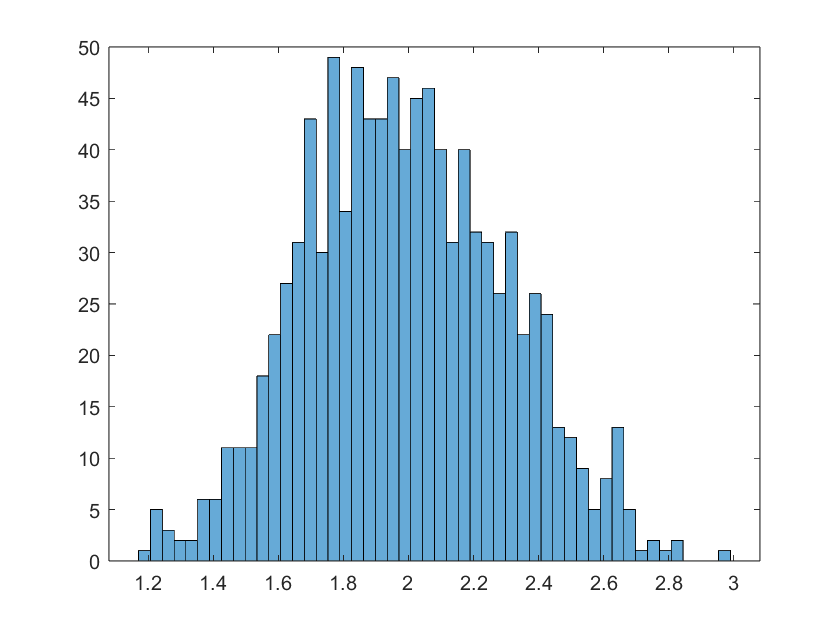

x = 2+randn([1,1000])*sqrt(0.1);
histogram(x,50)

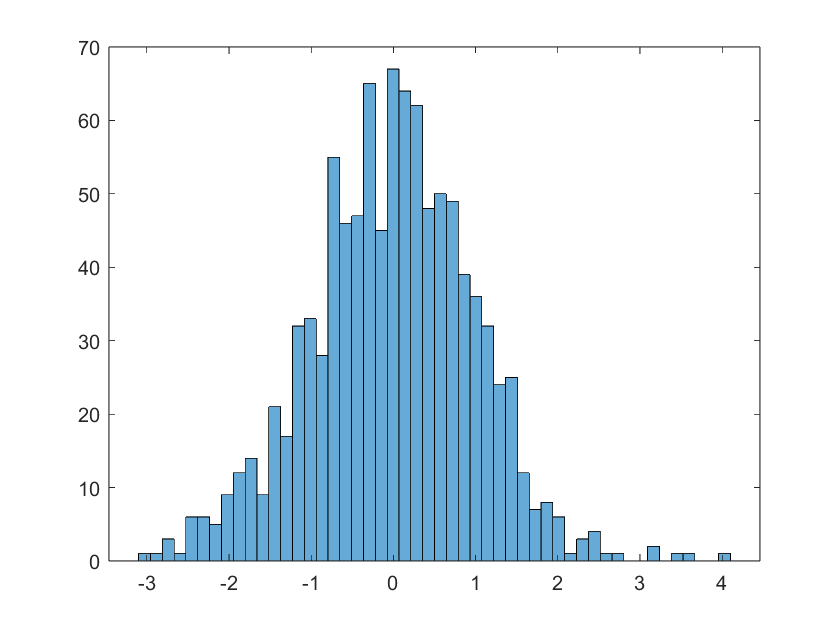

x = 0+randn([1,1000])*1;
histogram(x,50)

## `3.4 ``多项式`

#### `Q3.4 已知两个多项式`$y_1$`和`$y_2$`如下`


$$y_1=x^4-3x^3+2x^2+x+2
\\
y_2=3x^5+2x^3+x^2+7$$


`求`$$y_1+y_2,y_1-y_2,y_1\otimes y_2,[S,R]=y_1/y_2$$

`其中`$S$`为商多项式，`$R$`为余数多项式`

p1 = [0,4,-3,2,1,2];
p2 = [3,0,2,1,0,7];


$$$y_1+y_2$$$


p1+p2

ans =      3     4    -1     3     1     9



$$y_1-y_2$$


p1-p2

ans =     -3     4    -5     1     1    -5



$$y_1\otimes y_2$$


conv(p1,p2)

ans =      0    12    -9    14     1     7    32   -16    16     7    14



$$y_1/ y_2$$


[S,R] = deconv(p1,p2)

S = 0

R =      0     4    -3     2     1     2


#### `Q3.5 `用前面学到的函数分别求出Q3.4中两个多项式的根

r1 = roots(p1)

r1 =    0.7460 + 0.7929i
   0.7460 - 0.7929i
  -0.3710 + 0.5331i
  -0.3710 - 0.5331i


r2 = roots(p2)

r2 =   -1.1254 + 0.0000i
  -0.2821 + 1.2085i
  -0.2821 - 1.2085i
   0.8448 + 0.7954i
   0.8448 - 0.7954i


#### `Q3.6 `已知一个多项式y有5个根：-2, -1, 1, 3, 5，并且满足 y(0) = 1，请用前面学到的函数求出该多项式y。

root = [-2;-1;1;3;5];
coef= poly(root);
y0 = polyval(coef,0);
coef = coef / y0 % since y(0)=1, rescale it

coef =    -0.0333    0.2000    0.0667   -1.2000   -0.0333    1.0000


#### `Q3.7 `函数$\cos \left(x\right)$展开成幂级数为：


$$cos(x)\approx 1-\frac{x^2}{2!}+\frac{x^4}{4!}-\frac{x^6}{6!}+\frac{x^8}{8!}-\cdots$$


定义，$\textrm{P4}$为上述幂级数保留最高次数为4次的多项式（即前3项），$\textrm{P6}$为保留最高次数为6次的多项式（即前4项），$\textrm{P8}$为保留最高次数为8次的多项式……  令$x=\frac{\pi}{3}$，求出$cos(x),P4(x),P6(x),P100(x)$。 

x0 = pi / 3;
p4 = [0,-1/factorial(2),0,1];
p6 = [0,1/factorial(4),0,-1/factorial(2),0,1];
p8 = [0,-1/factorial(6),0,1/factorial(4),0,-1/factorial(2),0,1];

cos(x0)

ans = 0.5000

polyval(p4,x0)

ans = 0.4517

polyval(p6,x0)

ans = 0.5018

polyval(p8,x0)

ans = 0.5000

#### `Q3.8 `在控制系统中一般用传递函数来表达输入信号与输出信号之间的系统特征。下面是一 个机器人定位系统的传递函数，其中G(s)为系统传递函数，C(s)为系统输出信号，N(s)为系统输入信号，s为拉普拉斯变换复变量。


$$G(s)=\frac{C(s)}{N(s)}=\frac{s^3+9s^2+26s+24}{s^4+15s^3+77s^2+153s+90}$$


用MATLAB把G(s)变换成如下形式


$$G(s)=\frac{C(s)}{N(s)}=\frac{(s+a_1)(s+a_2)(s+a_3)}{(s+b_1)(s+b_2)(s+b_3)(s+b_4)}$$


pc = [1,9,26,24];
c = roots(pc)

c =    -4.0000
   -3.0000
   -2.0000


pn = [1,15,77,153,90];
n = roots(pn)

n =    -6.0000
   -5.0000
   -3.0000
   -1.0000


因此，解得


$$G(s)=\frac{C(s)}{N(s)}=\frac{(s+2)(s+3)(s+4)}{(s+1)(s+3)(s+5)(s+6)}$$


# `4 `MATLAB图形工具

## 4.1 二维图形曲线 

## 4.2 图形窗口操作

## 4.3 三维图形绘制

#### Q4.1 重复上述所有的样例代码，要求手工调整图形显示效果，记录每次显示出来的图形

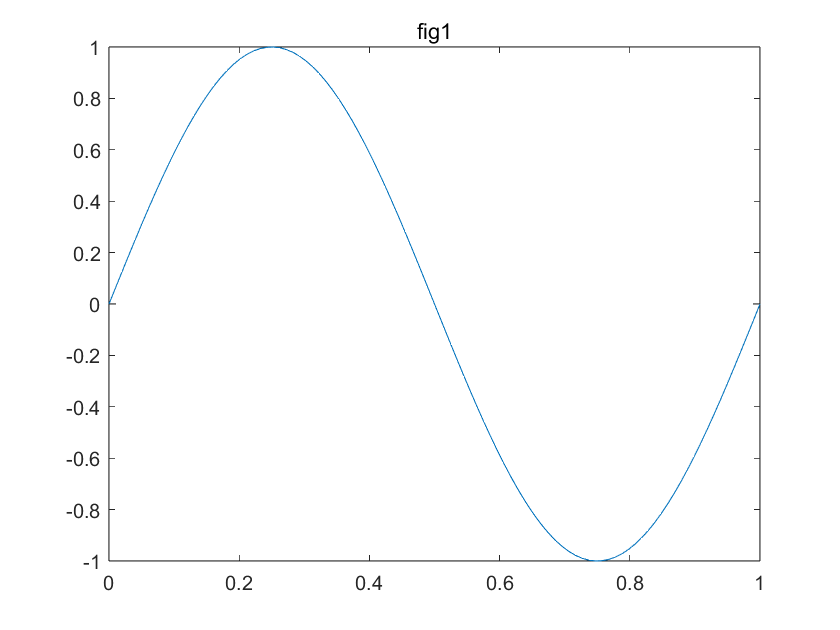

x = linspace(0,1,100);
y = sin(2*pi*x);
plot(x,y)
title('fig1')

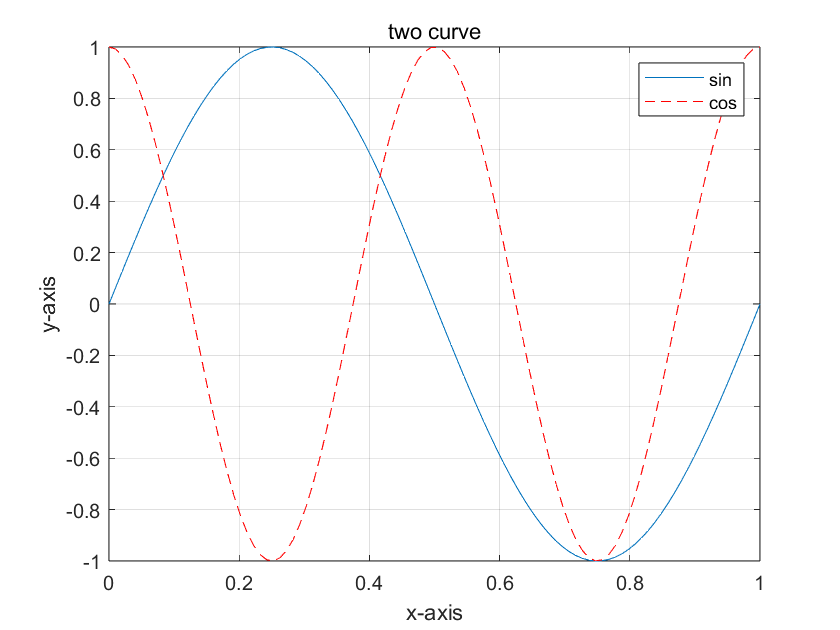

x = linspace(0,1,100);
y = sin(2*pi*x);
z = cos(2*pi*2*x);
plot(x,y,x,z,'r--'), grid on;
title('two curve');
xlabel('x-axis');
ylabel('y-axis');
legend('sin','cos')

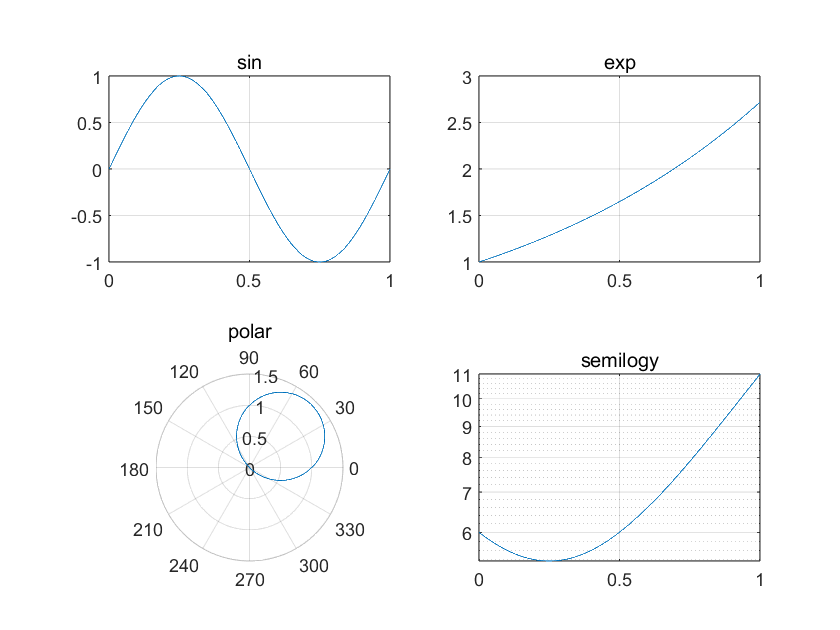

x = linspace(0,1,1000);
y1 = sin(2*pi*x);
y2 = exp(x);
h = linspace(0, 2*pi, 1000);
y3 = sin(h) + cos(h);
y4 = 10*x.^2 - 5*x + 6;
subplot(221), plot(x,y1), grid on, title('sin');
subplot(222), plot(x,y2), grid on, title('exp');
subplot(223), polarplot(h,y3), grid on, title('polar');
subplot(224), semilogy(x,y4), grid on, title('semilogy');

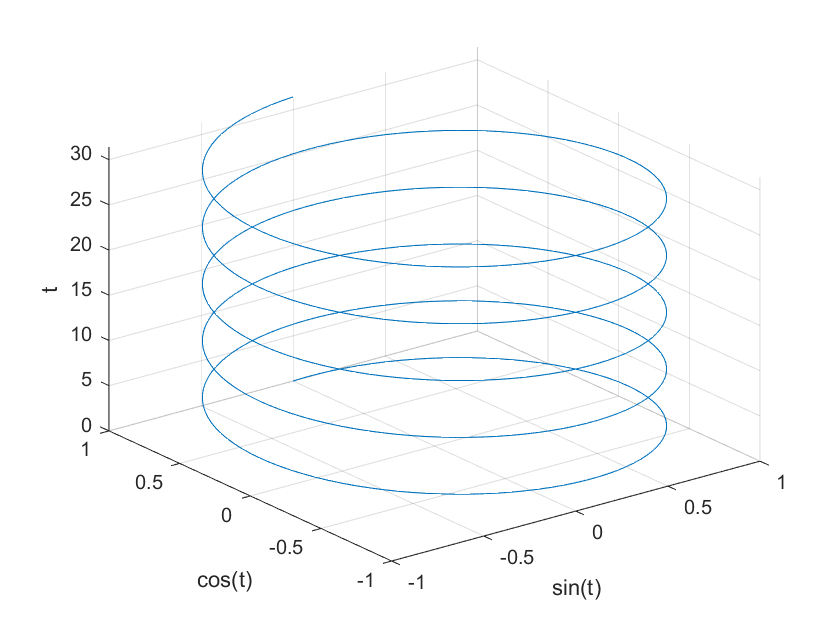

subplot(111)
t = 0:pi/50:10*pi;
plot3(sin(t),cos(t),t), grid on;
xlabel('sin(t)');
ylabel('cos(t)');
zlabel('t');

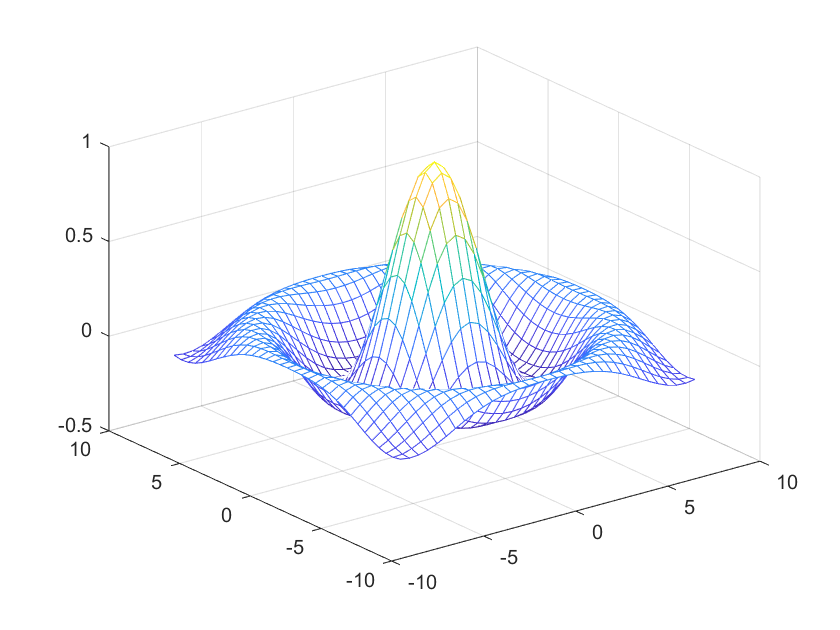

[X, Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z);

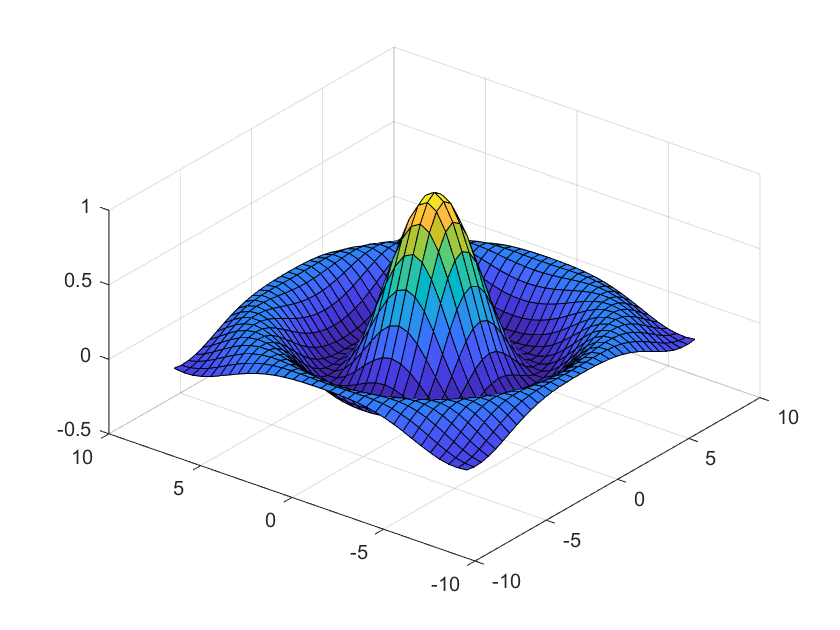

surface(X,Y,Z);

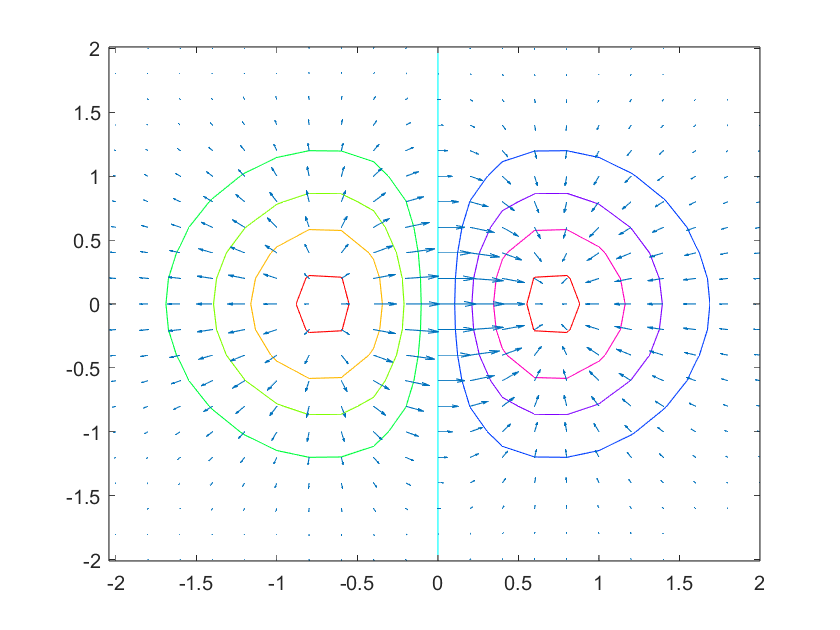

figure
[X, Y] = meshgrid(-2:.2:2);
Z = X.*exp(-X.^2-Y.^2);
[DX, DY] = gradient(Z,.2,.2);
contour(X,Y,Z)
hold on
quiver(X,Y,DX,DY)
colormap hsv
hold off

#### Q4.2 下面是蝴蝶曲线的参数方程组


$$x=sin(t)(e^{cos(t)}-2cos(4t)-sin^5(\frac{t}{12}))
\\
y=cos(t)(e^{cos(t)}-2cos(4t)-sin^5(\frac{t}{12}))$$


要求用MATLAB的subplot画出 x, y 与t之间的关系曲线、x与y之间的关系曲线。参数t的参考取值范围是0:1/16:100，改变t的取值，观看不同的蝴蝶形状。 

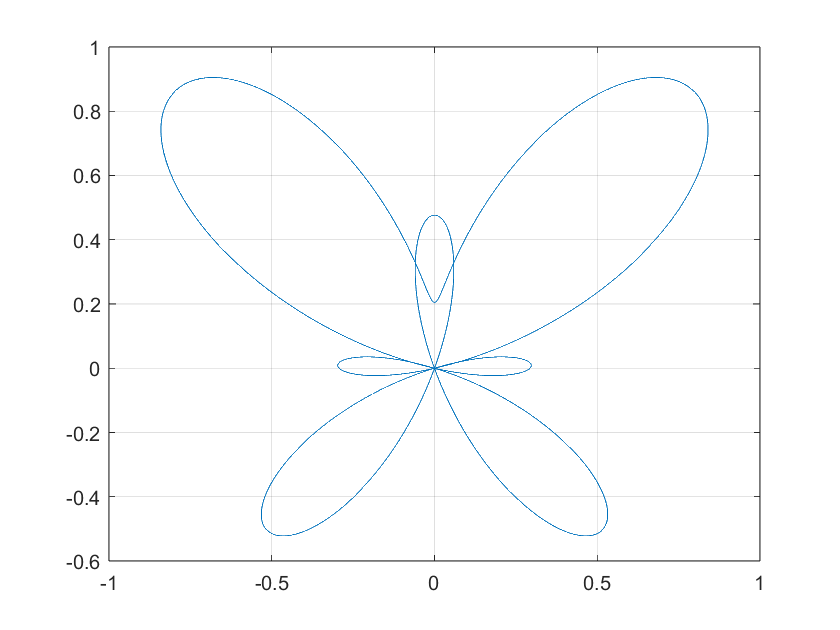

subplot(111)
t = 5.1:0.00001:45;
alpha = 0.29;
x = alpha * sin(t).*(exp(cos(t))-2*cos(4*t)-power(sin(5/12),5));
y = alpha * cos(t).*(exp(cos(t))-2*cos(4*t)-power(sin(5/12),5));
plot(x,y), grid on;

#### Q4.3 续上题，蝴蝶曲线也可以用如下的极坐标表达式


$$r=e^{sin\theta}-2cos4\theta-sin^5(\frac{2\theta-\pi}{24})$$


用polar函数绘制出该曲线，并且设置图的标题、XY轴标签、图例等

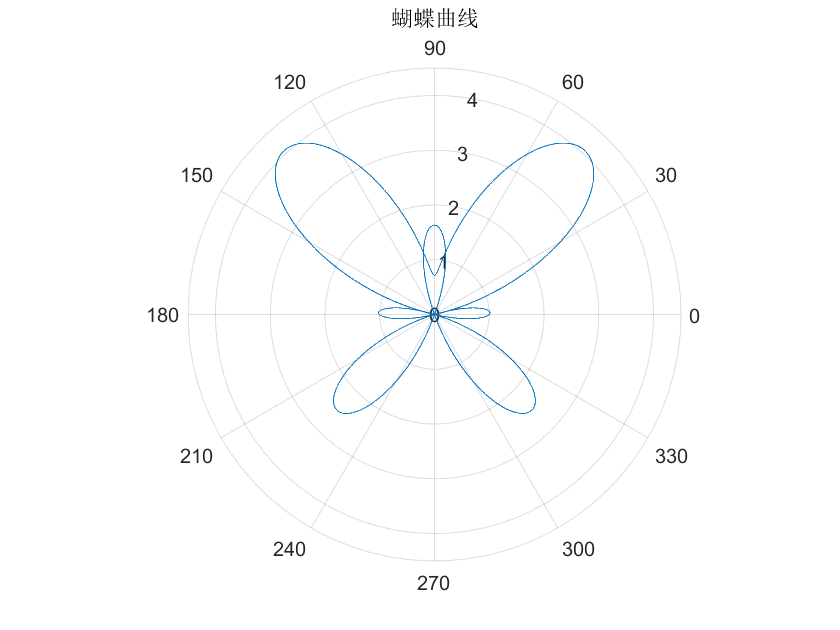

theta = linspace(0, 2*pi, 1000);
r = exp(sin(theta))-2*cos(4*theta)-power(sin((2*theta-pi)/24),5);
polarplot(theta,r), grid on, title('蝴蝶曲线');

#### Q4.4 下表列出了一组原始数据和建模回归后的数据


$$\matrix{
X&1&2&3&4&5&6\cr
Y_0&6&11.1&15.7&21&26&30.8\cr
Y_m&6&10.97&15.94&20.91&25.89&30.86
}$$


请在MATLAB下绘制这两组数据，其中Y0用红色圈、Ym用蓝色粗线条，配上图例

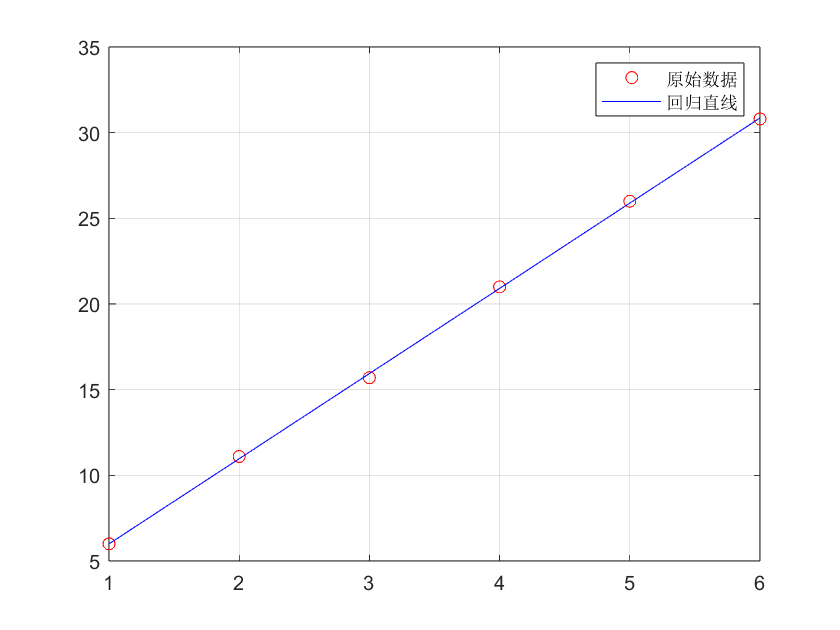

x = [1,2,3,4,5,6];
y0 = [6,11.1,15.7,21,26,30.8];
ym = [6,10.97,15.94,20.91,25.89,30.86];
plot(x,y0,'or',x,ym,'blue'), grid on;
legend('原始数据','回归直线')

# 五 非线性方程求根 

## Q5.1 二分法与迭代法

具体要求

- 调试通过上述迭代法程序，求解方程的根

- 参照上述迭代法程序，改写成二分法程序，求解同一方程

- 上交两个程序的源代码文件+运行结果的文本文件

设待求解函数为


$$f\left(x\right)=x^3 -2x$$


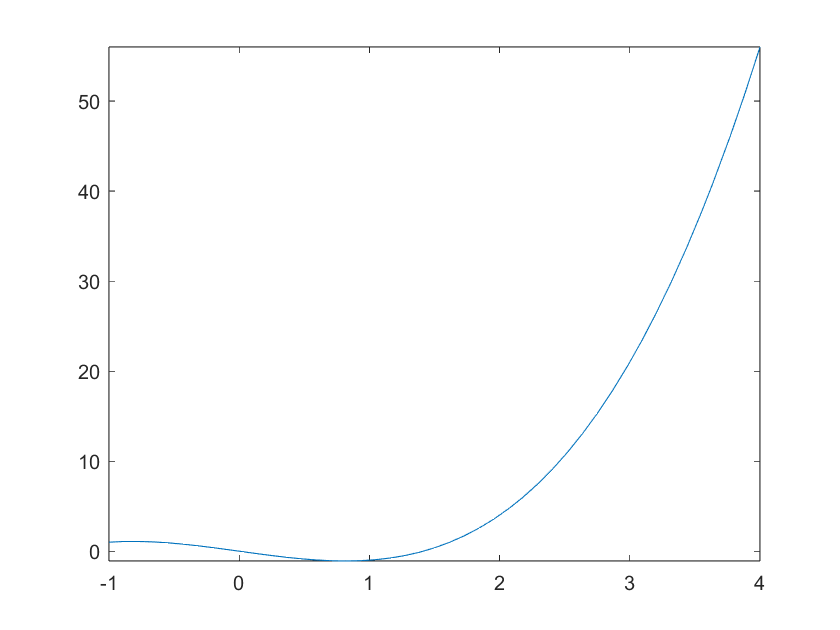

fun = @(x)power(x,3)-2*x;
fun_fix = @(x)1+1/(x*x);
fplot(fun,[-1,4])

[x, root_exists] = iterative_method(fun_fix, 100, 0.01)

x = 1.4629

root_exists = logical
   1


disp(fun(x));

    0.2051



[x, root_exists] = biselection_method(fun, 1, 100, 0.01)

x = 1.4139

root_exists = logical
   1


disp(fun(x));

   -0.0012



## Q5.2 牛顿法及混合算法

具体要求

- 编写(已提供的)单变量函数自动求导工具

- 编写牛顿迭代法

- 编写一个待求根的非线性函数，包括两个区间(a1,b1),(a2,b2)

- 可视化该函数

- 使用二分法+牛顿法对(a1,b1)进行求解

- 使用二分法+牛顿法对(a2,b2)进行求解

设待求解函数与5.1相同

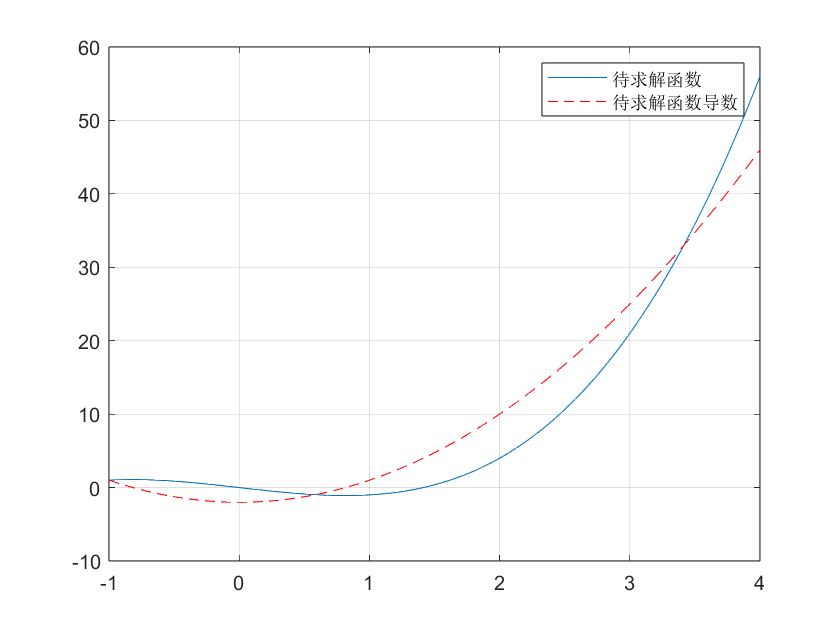

fun = @(x)power(x,3)-2*x;
%d_fun = @(x)first_derivative(fun, x, 0.01);
d_fun = @(x) (fun(x + 0.001) - fun(x - 0.001)) / (2 * 0.001);

x = linspace(-1,4,100);
y = fun(x);
dy = d_fun(x);
plot(x,y,x,dy,'r--'), grid on;
legend('待求解函数','待求解函数导数')

直接使用牛顿法进行求解：

%test = 100;
%disp([d_fun(test), first_derivative(fun,test,0.0001)]);
%first_derivative(fun,1.5,0.0001)
[x, root_exists] = newton_method(fun, 2, 0.01)

x = 1.4142

root_exists = logical
   1


使用二分法+牛顿法对(a1,b1)进行求解

[x0, root_exists] = biselection_method(fun, -1, 1, 0.1);
disp(x0);

     0



[x, root_exists] = newton_method(fun, x0, 0.00001);
disp(x);

     0



使用二分法+牛顿法对(a2,b2)进行求解

[x0, root_exists] = biselection_method(fun, 1, 2, 0.1);
disp(x0);

    1.4375



[x, root_exists] = newton_method(fun, x0, 0.00001);
disp(x);

    1.4142



# `六 `线性方程组求根--消元法

## Q6.1 消元法

A = [1,2,2;-2,-2,-1;2,-3,-2];
b = [3;-3;-1];
disp("消元前的增广矩阵");disp([A,b]);

消元前的增广矩阵
     1     2     2     3
    -2    -2    -1    -3
     2    -3    -2    -1



[U, bb] = Gaussian_Elimination(A, b);
disp("消元后的增广矩阵");disp([U,bb]);

消元后的增广矩阵
    1.0000    2.0000    2.0000    3.0000
         0    2.0000    3.0000    3.0000
         0         0    4.5000    3.5000



x = Back_Substitution(U, bb);
disp("解");disp(x);disp("验证常数向量");disp(A*x)

解
    0.7778
    0.3333
    0.7778

验证常数向量
    3.0000
   -3.0000
   -1.0000



# `七 `线性方程组求根--迭代法

A = [5,0.2,2;-0.2,-1,-0.1;1,-0.1,2];
b = [3;-3;-1];

disp([A, b]);

    5.0000    0.2000    2.0000    3.0000
   -0.2000   -1.0000   -0.1000   -3.0000
    1.0000   -0.1000    2.0000   -1.0000



L = tril(A, -1);
U = triu(A, 1);
D = A - L - U;

disp(L);disp(U);disp(D);

         0         0         0
   -0.2000         0         0
    1.0000   -0.1000         0

         0    0.2000    2.0000
         0         0   -0.1000
         0         0         0

     5     0     0
     0    -1     0
     0     0     2




B1 = -D\(L+U);
B2 = -(L+D)\U;

p1 = max(abs(eig(B1)));
p2 = max(abs(eig(B2)));

fprintf('雅可比迭代矩阵B谱半径=%8.6f,高斯赛德尔迭代矩阵B谱半径=%8.6f\n',p1,p2);

雅可比迭代矩阵B谱半径=0.455403,高斯赛德尔迭代矩阵B谱半径=0.196839


n = size(A, 1);
iter = 8;
solution_mid_jacobi = zeros(iter,1);
solution_mid_gauss = zeros(iter,1);
% Jacobi
tic;
x = ones(n,1);
for k = 1:iter
    x = D \ (-(L+U)*x + b);
    solution_mid_jacobi(k) = norm(x);
end
t_jacobi = toc;
fprintf('雅可比迭代时间=%8.6f\n',t_jacobi);disp(x);

雅可比迭代时间=0.019255
    0.7817
    2.9194
   -0.7422





% Gauss-Seidel
tic;
x = ones(n,1);
for k = 1:iter
    x = (D+L) \ (-U*x + b);
    solution_mid_gauss(k) = norm(x);
end
t_gauss = toc;
fprintf('高斯赛德尔迭代时间=%8.6f\n',t_gauss);disp(x);

高斯赛德尔迭代时间=0.013594
    0.7811
    2.9182
   -0.7447



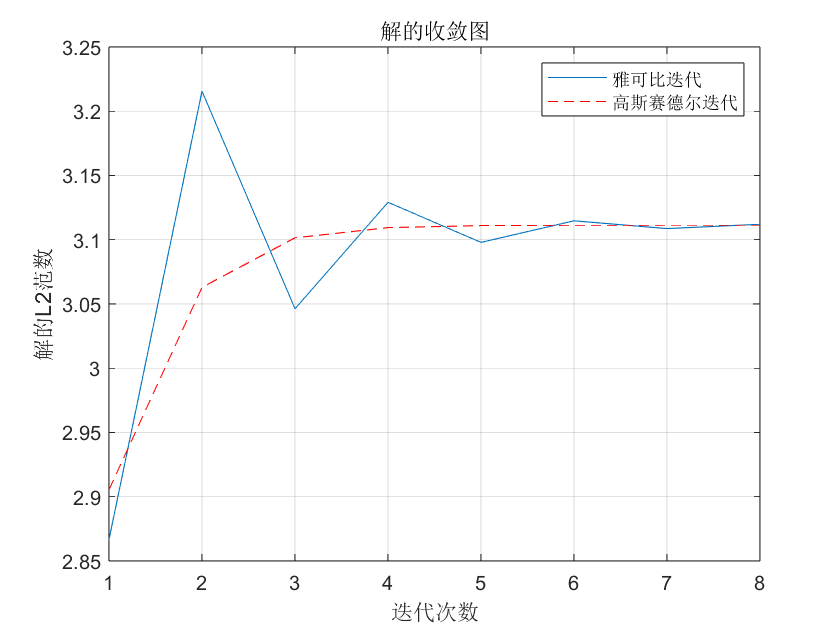

x = linspace(1,iter,iter);
y = sin(2*pi*x);
z = cos(2*pi*2*x);
plot(x,solution_mid_jacobi,x,solution_mid_gauss,'r--'), grid on;
title('解的收敛图');
legend('雅可比迭代','高斯赛德尔迭代');
xlabel("迭代次数");
ylabel("解的L2范数");

# `八 `矩阵特征值求解

## Q8.1 幂法、原点平移法、反幂法 

幂法

A = [2,1,3;2,5,1;1,2,1];
err = 0.01;
[l,v] = power_method(A, err);
[vs, ls] = eig(A);
disp('GT最大特征值，特征向量');disp(ls(1,1));disp(vs(:,1));disp('幂法最大特征值，特征向量');disp(l);disp(v);

GT最大特征值，特征向量
    6.5114

   -0.4317
   -0.8200
   -0.3759

幂法最大特征值，特征向量
    6.5087

    0.4319
    0.8199
    0.3759



原点平移法

P = -9.5;
B = A - P*eye(size(A,1));
[l,v] = power_method(B, err);
disp('原点平移法最大特征值');disp(l+P);

原点平移法最大特征值
    6.5082



反幂法

[l,v] = power_method(pinv(A), err);
disp('GT最小特征值');disp(ls(3,3));disp('反幂法最小特征值');disp(1/l);

GT最小特征值
    0.2475

反幂法最小特征值
    0.2471



# 九  多项式插值

## Q9.1 朗格朗日插值、牛顿插值 

xi = 0:0.1:pi;
yi = sin(xi);
xx = 0.15:0.2:pi;

tic;
for i = 1:10
    yy = Lagrange_Interp(xi,yi,xx,0);
end
t0 = toc;

tic;
for i = 1:10
    yy = Lagrange_Interp(xi,yi,xx,1);
end
t1 = toc;

fprintf("方法1运行时间%8.6f,方法2运行时间%8.6f",t0,t1);

方法1运行时间0.012051,方法2运行时间0.010184

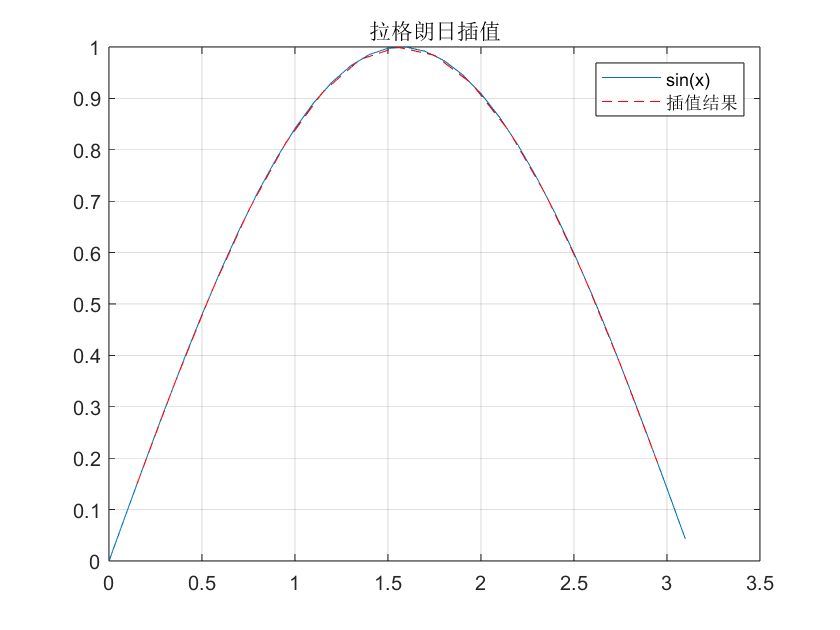


plot(xi,yi,xx,yy,'r--'), grid on;
title('拉格朗日插值');
legend('sin(x)','插值结果');

Runge现象演示

runge_fun = @(x) 1./(x.^2+1);
gen_point = @(x) linspace(-10,10,x)

gen_point = 包含以下值的 function_handle :
    @(x)linspace(-10,10,x)


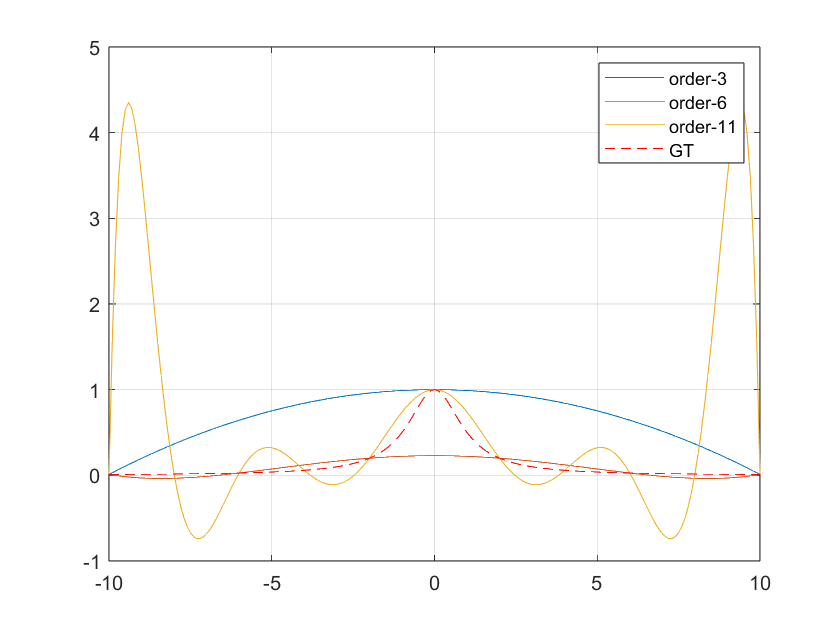

xx = (-10:0.1:10)';
yy0 = runge_fun(xx);

xi1 = gen_point(3);
yi1 = runge_fun(xi1);

xi2 = gen_point(6);
yi2 = runge_fun(xi2);

xi3 = gen_point(11);
yi3 = runge_fun(xi3);

yy1 = Lagrange_Interp(xi1,yi1,xx,1);
yy2 = Lagrange_Interp(xi2,yi2,xx,1);
yy3 = Lagrange_Interp(xi3,yi3,xx,1);

%err = zeros([3,1]);
err(1) = sum((yy1-yy0).^2);
err(2) = sum((yy2-yy0).^2);
err(3) = sum((yy3-yy0).^2);


plot(xx,yy1,xx,yy2,xx,yy3,xx,yy0,'r--'), grid on;
legend('order-3','order-6','order-11','GT');

disp(err)

   67.4327
    7.4137
  348.3911



# 十  最小二乘拟合与样条插值

## Q10.1 基础练习

已知如下测量数据，分别用样条插值和拟合法来编程求解问题。

- 用样条插值法（spline）来求解当 t = [0.3, 2.5, 4.1, 5.3, 7.6, 8.2] 时对应的y值。

- 用最小二乘法（矩阵形式）来拟合上述数据，设定的拟合模型为$y=\frac{t}{a+bt}$

- 熟悉多项式拟合函数（观看polyfit和polyval的doc），用polyfit函数重做上述第2问题， 并对比验证第2问题的程序正确性。 

x = linspace(1,8,8);
y = [4,6,8,8.8,9.22,9.5,9.7,9.86];
t = [0.3, 2.5, 4.1, 5.3, 7.6, 8.2];

r_s = spline(x,y,t);
disp(r_s);

    3.5529    7.1112    8.8472    9.3173    9.7991    9.8896



使用最小二乘法：


$$\pmatrix{y&ty}\pmatrix{a\cr b}=t
$$



$$\pmatrix{y&ty}^T\pmatrix{y&ty}\pmatrix{a\cr b}=\pmatrix{y&ty}^Tt$$


A = zeros([8,2]);
A(:,1) = y';
A(:,2) = (x.*y)';
p = (A'*A)\(A'*(x'));
%disp(r_ls);

fun=@(x)x./(p(1)+p(2).*x);
r_ls = fun(t);
disp(r_ls)

    1.8735    7.2786    8.5987    9.1882    9.8893   10.0182



使用polyfit

p = polyfit(x,y,5);
r_p = polyval(p,t)

r_p =     3.3081    7.0629    8.9426    9.2914    9.8978    9.7413


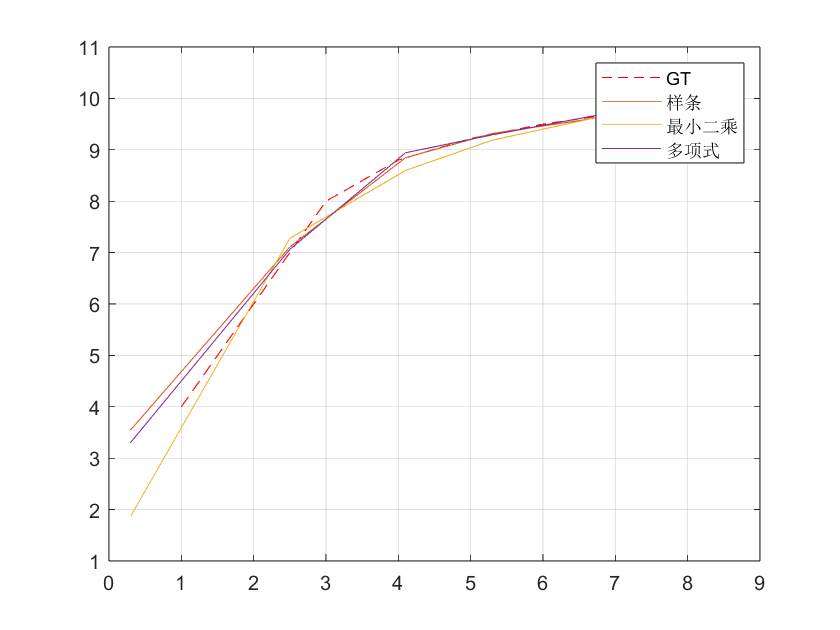

plot(x,y,'r--',t,r_s,t,r_ls,t,r_p), grid on;
legend('GT','样条','最小二乘','多项式');

## Q10.2 增强练习

假定真实规律为：$y=\sin \left(10\pi x\right)$

- 在$x\in[0,1]$中均匀采集100个点，得到100组精确的数据$(x_0,y_0)$其中$x_0$和$y_0$均为含有100个元素的列向量（参见linspace函数）。另外在$x\in[0,1]$区间均匀采集1000个点，得到$(x_2,y_2)$供插值和拟合验证使用。  

- 对$y_0$加入高斯概率分布的噪声，噪声强度为10dB（参见awgn函数的doc），加噪后的数据记为$y_{10}$。同样加20dB噪声后的数据记为$y_{20}$，在同一坐标轴下画出$y_0$、$y_{10}$、$y_{20}$三条曲线，对比观看。  

- 用样条插值对数据集$(x_0,y_{10})$和$(x_0,y_{20})$进行建模，并求出$x_2$所对应的$s_{10}$和$s_{20}$，把曲线$(x_2,y_2)$、插值曲线$(x_2,s_{10})$和$(x_2,s_{20})$画在同一坐标轴下，观看插值情况。  

- 用多项式（20次方）最小二乘法对数据集) , $(x_0,y_{10})$和$(x_0,y_{20})$进行拟合建模，并求出$x_2$所对应的$p_{10}$和$p_{20}$，把曲线$(x_2,y_2)$、插值曲线$(x_2,p_{10})$和$(x_2,p_{20})$画在同一坐标轴 下，观看拟合情况。 

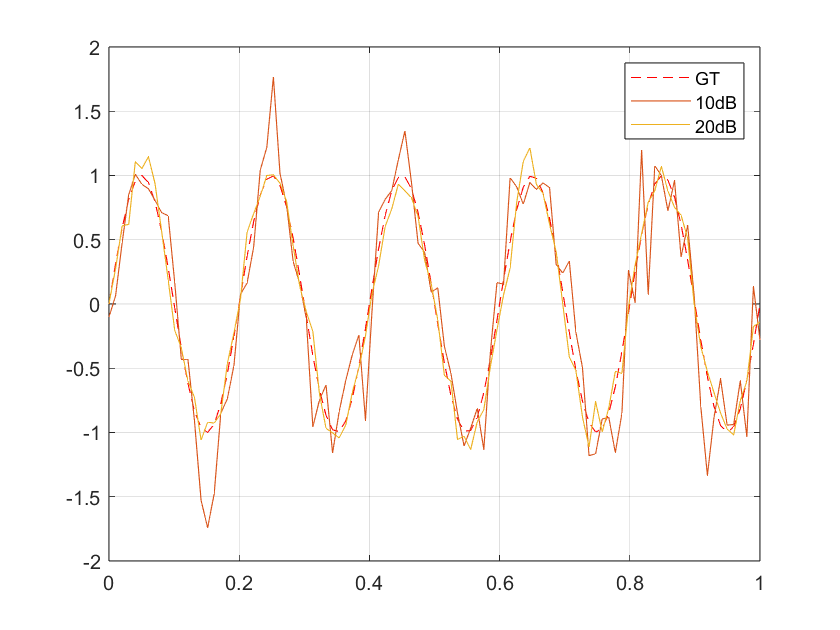

f = @(x)sin(10*pi.*x);
x0 = linspace(0,1,100)';
y0 = f(x0);

x2 = linspace(0,1,1000)';
y2 = f(x2);

y10 = awgn(y0,10);
y20 = awgn(y0,20);

plot(x0,y0,'r--',x0,y10,x0,y20), grid on;
legend('GT','10dB','20dB');

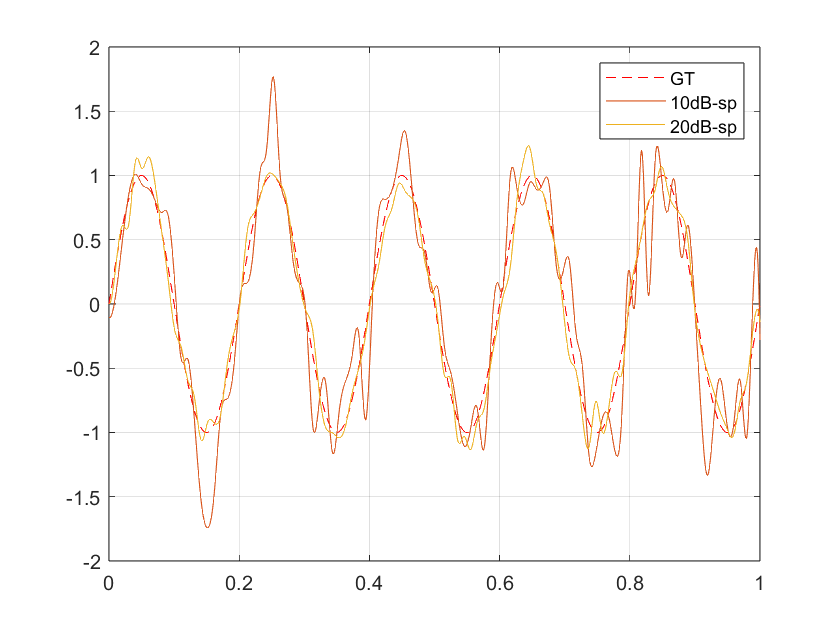


s10 = spline(x0,y10,x2);
s20 = spline(x0,y20,x2);

plot(x2,y2,'r--',x2,s10,x2,s20), grid on;
legend('GT','10dB-sp','20dB-sp');

p_ = polyfit(x0,y10,20);

p__ = polyfit(x0,y20,20);

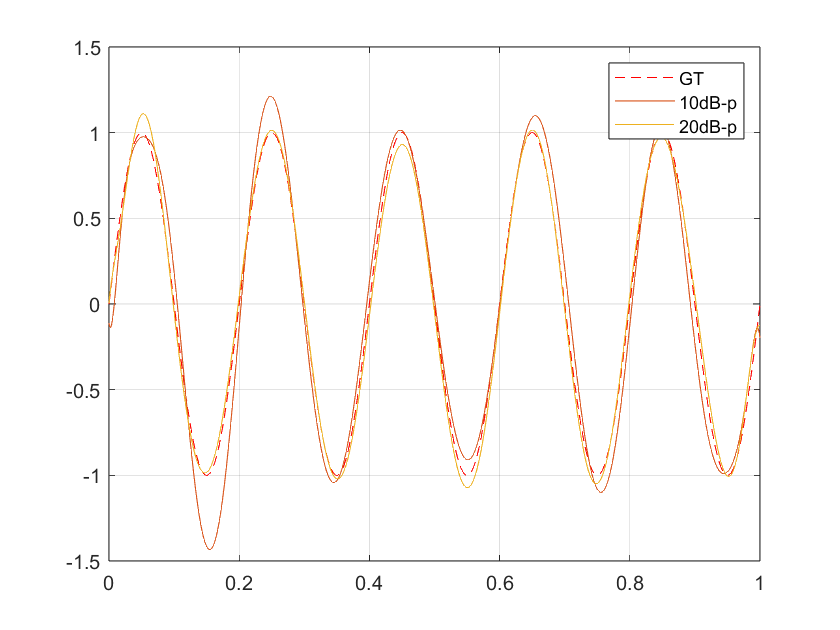

p10 = polyval(p_,x2);
p20 = polyval(p__,x2);

plot(x2,y2,'r--',x2,p10,x2,p20), grid on;
legend('GT','10dB-p','20dB-p');

# 十一  数值积分

## Q11.1 牛顿科特斯积分  

对于如下的定积分


$$I=\int^1_0\frac{1}{1+x^2}\mathrm{d}x$$


按如下要求各自编程求解：  

- 单区间的梯形积分T1、两个小区间的梯形积分T2、三个小区间的梯形积分T3、四个小区间梯形积分T4  

- 两个小区间的辛普森积分S1、四个小区间的辛普森积分S2  

- 四个小区间的牛顿科特斯积分K4  并对比各个积分值之间的误差。

### 梯形积分

fun = @(x)1./(1+x.^2);
x = linspace(0,1,2);
y = fun(x);
I = trapz(x, y);
fprintf("%.10f",I);

0.7500000000

x = linspace(0,1,3);
y = fun(x);
I = trapz(x, y);
fprintf("%.10f",I);

0.7750000000

x = linspace(0,1,4);
y = fun(x);
I = trapz(x, y);
fprintf("%.10f",I);

0.7807692308

x = linspace(0,1,5);
y = fun(x);
I = trapz(x, y);
fprintf("%.10f",I);

0.7827941176

### 辛普森积分

I = (fun(0)+4*fun(0.5)+fun(1))/6;
fprintf("%.10f",I);

0.7833333333

### 牛顿科茨积分

I = (7*fun(0)+32*fun(0.25)+12*fun(0.5)+32*fun(0.75)+7*fun(1))/90;
fprintf("%.10f",I);

0.7855294118

## Q11.2 复化积分

用复化梯形、复化辛普森积分来求解Q11.1中的定积分，要求：

- 取小区间数为n = 64，编程计算 T64、S32，并对比误差精度；

- 输入附送的源代码，调试通过并运行，查看积分结果、迭代次数（区间个数），其中设定err = 0.0001。 

fun = @(x)1./(1+x.^2);

### 复化梯形

sum = 0;
N = 64;
h = 1/N;
for i = 1:N
    sum = sum + (fun((i-1)*h)+fun(i*h))*h/2;
end
fprintf("%.10f",sum);

0.7853879909

### 复化辛普森积分

sum = 0;
N = 32;
h = 1/N;
for i = 1:N
    sum = sum + (fun((i-1)*h)+4*fun((i-0.5)*h)+fun(i*h))*h/6;
end
fprintf("%.10f",sum);

0.7853981634

### 指导书提供的迭代辛普森积分

I = Interval_Halving_Trapz(fun, 0, 1, 0.0001);
fprintf("%.10f",I);

0.7853879909

## Q11.3 龙贝格积分

用附送的源代码求解Q11.1中的定积分

fun = @(x)1./(1+x.^2);
[q,ea,iter] = romberg(fun, 0, 1, 0.0001, 10000);
fprintf("%.10f",q);

0.7853981663

# 十二  常微分方程求解

## Q12.1 欧拉法 

上机要求：  

- 读懂附送的源代码

- 修改 Fxy 函数以及x0,y0等参数，看看结果

- 自行编写梯形法、改进欧拉法

- 测试自己编写的算法是否正确，对比五种欧拉法的误差 

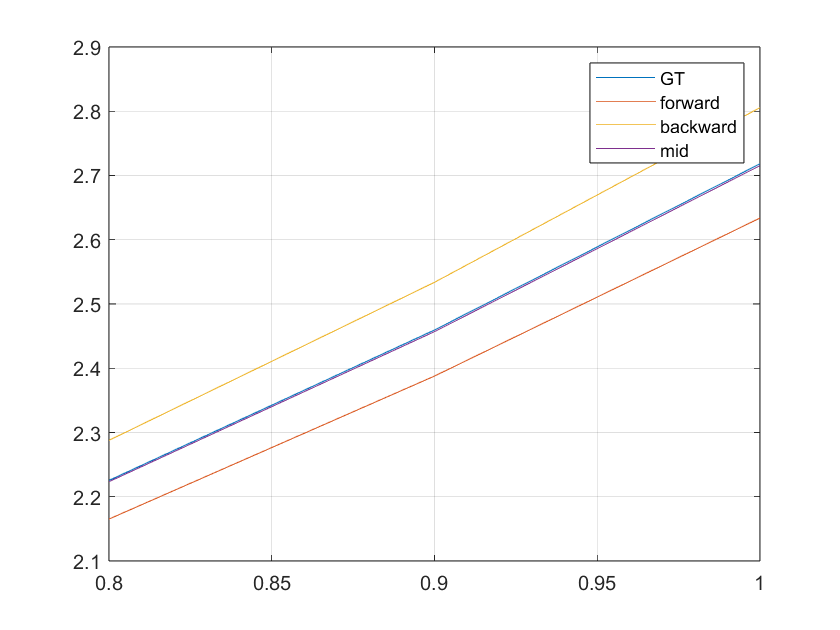

Fxy = @(x,y)exp(x);
x0 = 0;
y0 = 1;
h = 0.1;
n = 10;
[~,yy1] = euler(Fxy,x0,y0,h,n,1);
[~,yy2] = euler(Fxy,x0,y0,h,n,2);
[xx,yy4] = euler(Fxy,x0,exp(-0.1),h,n,4, y0);
yy0 = exp(xx);
figure, plot(xx,[yy0,yy1,yy2,yy4]), grid on;
xlim([0.8 1]);
legend('GT','forward', 'backward', 'mid')

梯形法、改进欧拉法

改进欧拉法：先用显式欧拉法计算下一点的y值，然后用该预测值计算下一点处的导数，将这个导数与当前点的导数取均值，作为当前点的步进的权重

梯形法就是implicit的改进欧拉法，即下一个点的导数值由隐式欧拉法估计（改进欧拉法由显式欧拉法估计）

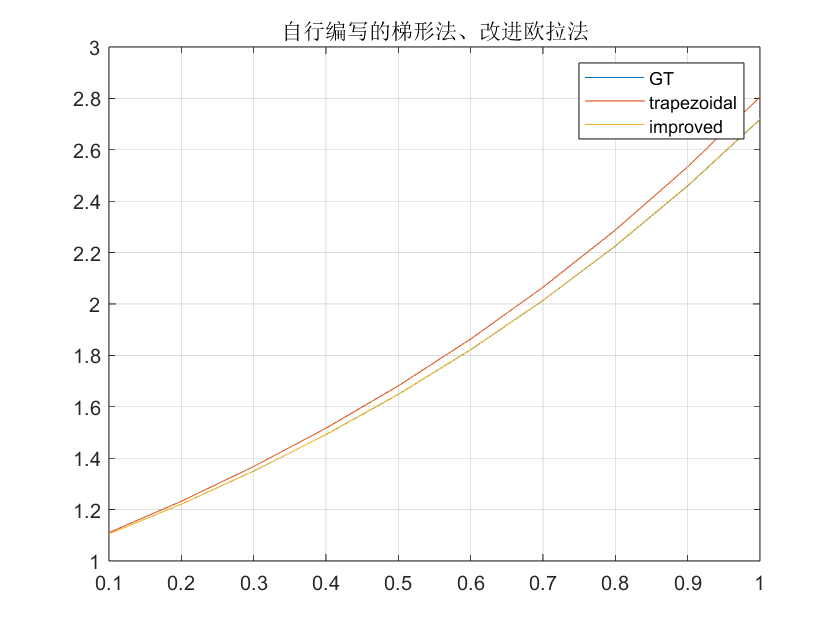

Fxy = @(x,y)exp(x);
x0 = 0;
y0 = 1;
h = 0.1;
n = 10;

[~,yy3] = euler(Fxy,x0,y0,h,n,3);
[~,yy5] = euler(Fxy,x0,y0,h,n,5);
plot(xx,[yy0,yy3,yy5]), grid on;
legend('GT','trapezoidal', 'improved')
title("自行编写的梯形法、改进欧拉法")

## Q12.2 龙格库塔法

下面的代码实现了洛仑兹方程曲线的绘制。其中自定义函数 do_Lorenz 需要保存到M 文件中。请读懂代码并绘制出曲线（函数ode45是龙格库塔法）。 

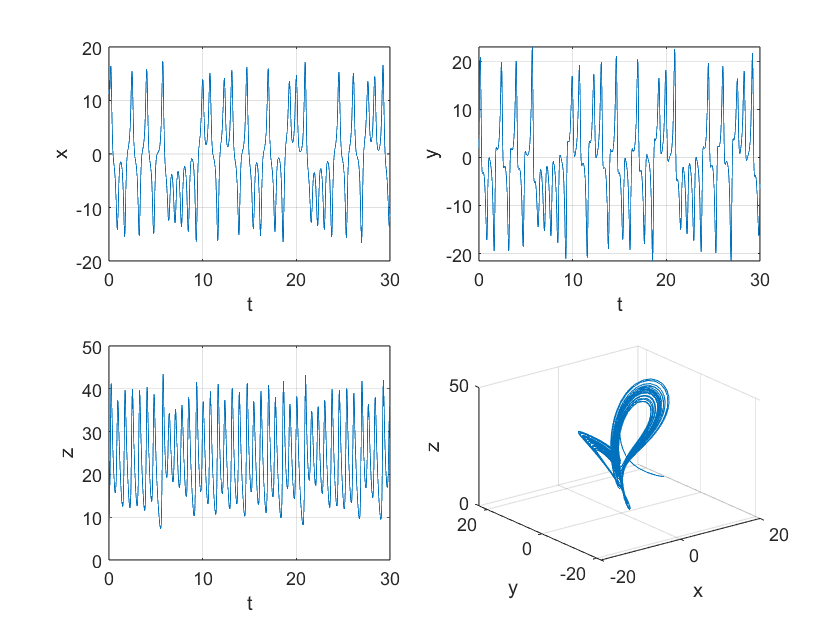

[t,y] = ode45(@Lorenz, [0,30], [12,2,9]);
subplot(221),plot(t,y(:,1)),grid on;xlabel('t');ylabel('x');
subplot(222),plot(t,y(:,2)),grid on;xlabel('t');ylabel('y');
subplot(223),plot(t,y(:,3)),grid on;xlabel('t');ylabel('z');
subplot(224),plot3(y(:,1),y(:,2),y(:,3)),grid on;xlabel('x');ylabel('y');zlabel('z');

# 十四  综合练习

## Q14.1 迭代思维编程

### 1 重复上述三个问题的源码，以及测试，要求达到一样的结果。

用迭代法求解非线性方程的根 

ddf_fun = @(x,theta)cos(x);
[XX,D1] = ddf(ddf_fun,1,0.001,1000,[]);
disp(D1);disp(XX(D1));

    16

    0.7396



用幂法求解矩阵的谱半径和对应的特征向量

lambda0 = 0;
k = 0;
e0 = 0.0001;
iter_max = 1000;
iter = 0;

A = [1,2,1;2,1,2;3,4,2];
x0 = rand(size(A,1), 1);

while iter < iter_max
    x1 = A * x0;
    lambda = mean(x1./x0);
    if iter>1
        e1 = norm(lambda0-lambda);
    else
        e1 = e0+1;
    end
    
    if e1 < e0
        break;
    end
    
    iter = iter +1;
    x0=x1;
    lambda0=lambda;
end

disp(iter);

     7



disp(lambda);

    5.8100



disp(x1/max(abs(x1)));

    0.4604
    0.6072
    1.0000



用二分法求解非线性方程 

f = @(x)x-cos(x);
[x, root_exists] = biselection_method(f, 0.5, 1, 0.001, 1000);
fprintf("%.10f",x);

0.7392578125

### 2 改变迭代的最大允许误差，例如改成0.00001、1.0e-8等，观看结果的精度

[x, root_exists] = biselection_method(f, 0.5, 1, 1.0e-6, 1000);
fprintf("%.10f",x);

0.7390851974

[x, root_exists] = biselection_method(f, 0.5, 1, 1.0e-8, 1000);
fprintf("%.10f",x);

0.7390851378

### 3 读懂上述三个问题的思路和源码，模仿这些源码编写一个用牛顿法程序求解如下方程

f = @(x)x-(x-cos(x))/(1+sin(x));
[x, root_exists] = iterative_method(f, 0.5, 0.001, 1000);
fprintf("%.10f",x);

0.7390851339

### 4 编写一个用雅克比迭代法程序求解如下线性方程组


$$\pmatrix{
1&0.4&0.4\cr
0.4&1&0.8\cr
0.4&0.8&1\cr
}
\pmatrix{
x_1\cr
x_2\cr
x_3\cr
}
=
\pmatrix{
1\cr
2\cr
3\cr
}$$


A = [1,0.4,0.4;0.4,1,0.8;0.4,0.8,1];
b = [1;2;3];
L = tril(A, -1);
U = triu(A, 1);
D = A - L - U;
n = size(A, 1);
iter = 8;
solution_mid_jacobi = zeros(iter,1);
solution_mid_gauss = zeros(iter,1);
% Jacobi
tic;
x = ones(n,1);
for k = 1:iter
    x = D \ (-(L+U)*x + b);
    solution_mid_jacobi(k) = norm(x);
end
t_jacobi = toc;
fprintf('雅可比迭代时间=%8.6f\n',t_jacobi);disp(x);

雅可比迭代时间=0.007707
   -0.1391
   -0.6672
    3.4940



# iterative_method

Q5.1作业-基于迭代法的非线性方程求解器

传入参数

- f: 待求解的函数，如sin、或者自定义的函数

- x0: 迭代求解的初始值

- e: 迭代求解的误差上限

- iter_max(可选): 最大迭代次数

返回值

- x: 解

- root_exists: 解是否存在（当且仅当root_exists=true时，x为函数的在满足误差下的根）

function [x, root_exists] = iterative_method(f, x0, e, iter_max)
    if nargin < 4
        iter_max=1000;
    end
    root_exists = false;
    iter = 0;
    while iter < iter_max
        x = f(x0);
        if abs(x-x0)<e
            root_exists = true;
            break;
        end
        iter = iter + 1;
        x0 = x;  
    end
end

# biselection_method

Q5.1作业-基于二分法的非线性方程求解器

传入参数

- f: 待求解的函数，如sin、或者自定义的函数

- x0: 实根所在区间(左)

- x1: 实根所在区间(右)

- e: 迭代求解的误差上限

- iter_max(可选): 最大迭代次数

返回值

- x: 解

- root_exists: 解是否存在（当且仅当root_exists=true时，x为函数的在满足误差下的根）

function [x, root_exists] = biselection_method(f, x0, x1, e, iter_max)
    if nargin < 5
        iter_max=1000;
    end
    
    if sign(f(x0)) * sign(f(x1)) >= 0
        disp([f(x0), f(x1)])
        disp('根不确定');
    end
    root_exists = false;
    iter = 0;
    while iter < iter_max
        x = (x0+x1)/2;
        if abs(f(x)) < e
            root_exists = true;
            break;
        end
        
        if(sign(f(x0))*sign(f(x))<0) % root in left section
            x1 = x;
        else
            x0 = x;
        end
        
        iter = iter + 1; 
    end
end

# first_derivative

Q5.2作业-基于差分法的单变量函数自动求导函数

传入参数

- f: 待求解的函数，如sin、或者自定义的函数

- x0: f定义域上的某一点

- e: 差分法的误差上限

- iter_max(可选): 最大迭代次数

返回值

- x: x0处的一阶导数值

function x = first_derivative(f, x0, e, iter_max)
if nargin < 4
   iter_max=10000;
end

if x0 == 0
    dx = 1.0e-2;
else
    dx = 0.1*x0;
end

df0 = inf;
iter = 0;
while iter < iter_max
    f1 = f(x0-dx);
    f2 = f(x0+dx);
    df1 = (f2-f1)/(2*dx);
    if(abs(df1-df0)<e)
        break;
    else
        df0 = df1;
        iter = iter + 1;
        dx = dx / 2;
    end
end
x = df1;
end

# newton_method

Q5.2作业-基于牛顿法的非线性方程求解器

传入参数

- f: 待求解的函数，如sin、或者自定义的函数

- x0: 迭代求解的初始值

- e: 迭代求解的误差上限

- iter_max(可选): 最大迭代次数

返回值

- x: 解

- root_exists: 解是否存在（当且仅当root_exists=true时，x为函数的在满足误差下的根）

function [x, root_exists] = newton_method(f, x0, e, iter_max)
    if nargin < 4
        iter_max=1000;
    end
    root_exists = false;
    iter = 0;
    while iter < iter_max
        x = x0 - f(x0)/first_derivative(f, x0, e);
        if abs(x-x0)<e
            root_exists = true;
            break;
        end
        iter = iter + 1;
        x0 = x;  
    end
end

# Gaussian_Elimination

Q6.1作业-消元法-高斯分解

传入参数

- A: 系数矩阵

- b: 常数向量

返回值

- U: 上三角系数矩阵

- bb: 消元后的非齐次列向量

function [U,bb] = Gaussian_Elimination(A, b)
C = [A, b];
n = length(b);
for k = 1:n-1 % iter n-1 times
    L = eye(n);
    for i = k+1:n
        mik = C(i,k)/C(k,k);
        L(i,k) = -1 * mik;
    end
    C = L * C;
end
U = C(:,1:n);
bb = C(:,n+1);
end

# Back_Substitution

Q6.1作业-消元法-回代

传入参数

- U: 上三角系数矩阵

- bb: 消元后的非齐次列向量

返回值

- x: 解

function x = Back_Substitution(U, bb)
n = length(bb);
x = zeros(n, 1);
x(n) = bb(n) / U(n,n);
for i = (n-1):-1:1
    x(i) = (bb(i)-U(i,(i+1):n)*x((i+1):n)) / U(i,i);
end
end

# power_method

function [eigenval_max, vec]=power_method(A, e)
v0 = ones(size(A,1),1);
iter_max = 1000;
iter = 0;
while iter < iter_max
    v1 = A*v0;
    eigenval_max = mean(v1./v0);
    if std(v1./v0)<=e
        break;
    end
    v0 = v1;
    iter = iter + 1;
end
vec = v1/sqrt(sum(v1.^2));
end

# Lagrange_Interp

function yy=Lagrange_Interp(xi, yi, xx, method)
n = length(xi);
m = length(xx);
yy = zeros(m, 1);

if method == 0
    for j = 1:m
        L = zeros(n, 1);
        for k = 0:n-1
            L(k+1) = 1;
            for s = 0:n-1
                if k ~= s
                    L(k+1) = L(k+1)*(xx(j)-xi(s+1))/(xi(k+1)-xi(s+1));
                end
            end
        end
        for k = 0:n-1
            yy(j) = yy(j) + L(k+1)*yi(k+1);
        end
    end
elseif method == 1
    L = ones(m,n);
    for j = 1:m
        for k = 0:n-1
            for s = 0:n-1
                if k~=s
                    L(j,k+1) = L(j,k+1)*(xx(j)-xi(s+1))/(xi(k+1)-xi(s+1));
                end
            end
        end
    end
    yy = L*yi(:);   
end
end


# Interval_Halving_Trapz

function I = Interval_Halving_Trapz(f, a, b, err)
n = 1;
iter_max = 100;
iter = 0;
T1 = (b-a)*(f(a)+f(b))/2;
while iter < iter_max
    n = 2*n;
    x = linspace(a, b, n+1);
    h = x(2) - x(1);
    y = f(x);
    T2 = (h/2) * (y(1) + 2*sum(y(2:n)) + y(n+1));
    if abs(T2-T1)<err
        break;
    end
    iter = iter + 1;
    T1 = T2;
end
I = T2;
end

# romberg

function [q,ea,iter] = romberg(fun, a, b, es, iter_max)
n = 1;
I(1,1) = trapz(fun, a, b, n);
iter = 0;
while iter < iter_max
    iter = iter + 1;
    n = 2^iter;
    I(iter+1, 1) = trapz(fun, a, b, n);
    for k = 2:(iter+1)
        j = 2 + iter - k;
        I(j,k) = (4^(k-1)*I(j+1,k-1) - I(j,k-1)) / (4^(k-1)-1);
    end
    ea = abs((I(1, iter+1) - I(2, iter))) / I(1, iter+1)*100;
    if ea < es
        break;
    end
end
q = I(1, iter+1);
end

function I = trapz(fun, a, b, n)
x = a;
h = (b-a)/n;
s = fun(a);
for i = 1:n-1;
    x = x + h;
    s = s + 2*fun(x);
end
s = s + fun(b);
I = (b-a)*s/(2*n);
end

# euler

function yk=foward_euler(Fxy, xk_1, yk_1, h)
yk = yk_1 + h * Fxy(xk_1, yk_1);
end

function yk=backward_euler(Fxy, xk, yk_1, h)
yk = yk_1;
for s = 1:100
    yk1 = yk_1 + h*Fxy(xk, yk);
    if abs(yk1-yk) < 0.001
        break;
    end
    yk = yk1;
end
yk = yk1;
end

function yk=midpoint_euler(Fxy, xk_1, yk_2, yk_1, h)
yk = yk_2 + 2*h*Fxy(xk_1, yk_1);
end

function yk = trapezoidal(Fxy, xk_1, yk_1, h)
    k1 = Fxy(xk_1, yk_1);
    yk = yk_1;
    for s = 1:100
        yk1 = yk_1 + h*Fxy(xk_1, yk);
        if abs(yk1-yk) < 0.001
            break;
        end
        yk = yk1;
    end
    k2 = (yk-yk_1)/h;
    yk = yk_1 + (h / 2) * (k1 + k2);
end

function yk = improved_euler(Fxy, xk_1, yk_1,h)
    k1 = Fxy(xk_1, yk_1);
    k2 = Fxy(xk_1 + h, yk_1 + h * k1);
    yk = yk_1 + (h / 2) * (k1 + k2);
end

function [xx,yy] = euler(Fxy, x0,y0,h,n,OP,y1)
if nargin<5
    OP = 1;
end
xx = x0 + (1:n)'*h;
yy = zeros(n,1);
for k = 1:n
    % init
    if k==1
        xk_1 = x0;
        yk_1 = y0;
    else
        xk_1 = xx(k-1);
        yk_1 = yy(k-1);
    end
    %
    xk = xx(k);
    switch (OP)
        case 1
            yy(k) = foward_euler(Fxy, xk_1, yk_1, h);
        case 2
            yy(k) = backward_euler(Fxy, xk, yk_1, h);
        case 3
            yy(k) = trapezoidal(Fxy, xk, yk_1, h);
        case 4
            if k==1
                yk_1 = y1;
                yk_2 = y0;
            elseif k==2
                yk_1 = yy(1);
                yk_2 = y1;
            else
                yk_1 = yy(k-1);
                yk_2 = yy(k-2);
            end
            yy(k) = midpoint_euler(Fxy, xk_1, yk_2, yk_1, h);
        case 5
            yy(k) = improved_euler(Fxy, xk_1, yk_1,h);
    end
end

end

# Q12.2

function dy = Lorenz(~,y)
dy = zeros(3,1);
dy(1) = 10*(-y(1)+y(2));
dy(2) = 28*y(1)-y(2)-y(1)*y(3);
dy(3) = y(1)*y(2)-8/3*y(3);
end

# Q14.1

function [XX,D1] = ddf(f,x0,e0,D,theta)
N = length(x0);
if D ~= -1
    XX = zeros(N,D);
else
    XX = [];
end
iter=0;
while iter < D
    x1 = f(x0, theta);
    XX(:,iter+1) = x1;
    if norm(x1-x0)<e0
        break
    end
    iter = iter + 1;
    x0 = x1;
end
D1 = iter;
end